clear; clc;clf;
M = input('Enter the length of the filter');
wc = pi/3;
mby2 = (M - 1)/2;
n=0:M-1;
hd = sin(wc*(n-mby2))./(pi*(n-mby2))

hd =    -0.0551   -0.0689    0.0000    0.1378    0.2757       NaN    0.2757    0.1378    0.0000   -0.0689   -0.0551


hd(mby2+1) = wc/pi;
[H, W] = freqz(hd, 1)

H =    0.9122 + 0.0000i
   0.9119 - 0.0280i
   0.9108 - 0.0560i
   0.9089 - 0.0839i
   0.9064 - 0.1118i
   0.9031 - 0.1396i
   0.8990 - 0.1674i
   0.8942 - 0.1951i
   0.8887 - 0.2226i
   0.8825 - 0.2501i


W =          0
    0.0061
    0.0123
    0.0184
    0.0245
    0.0307
    0.0368
    0.0430
    0.0491
    0.0552


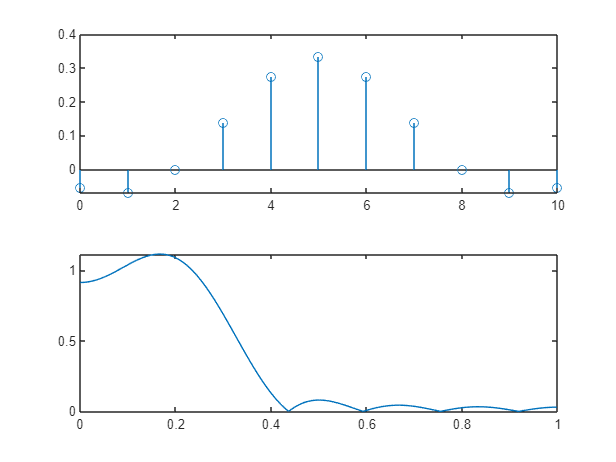

subplot(211), stem(n,hd);
subplot(212), plot(W/pi, abs(H));

figure